# Data ManipulationTest File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 09/05/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Enviroment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Set Directories & Load Data**

Load Signal data

% use your default user path to create the filename and path
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'))
load 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
load 'DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';

## 2. ASSET Data Manipulation

### 2.1 Nomralize the TRI series to have the first index value of each asset equal to 1. 

This creates a comparitive wealth series for each asset over the time period.

% Divide each element in each column of x by the first element of that column
ASSETCL_normalized_array = table2array(ASSETCL_TableFilled) ./ table2array(repmat(ASSETCL_TableFilled(1,:),height(ASSETCL_TableFilled),1));

% Convert the normalized array back to a timetable with the same timestamps as x
ASSETCL_normalized = array2timetable(ASSETCL_normalized_array, 'RowTimes', ASSETCL_TableFilled.Time);

% Copy the column names from x to x_normalized
ASSETCL_normalized.Properties.VariableNames = ASSETCL_TableFilled.Properties.VariableNames;

% Plot all asset normalized TRIs on a single plot
plot(ASSETCL_normalized.Time, table2array(ASSETCL_normalized))
ylabel("Normalized TRIs")
xlabel("Time")
title("Normalized Asset Class Wealth Series From TRIs")
% include the legend
legend(ASSETCL_normalized.Properties.VariableNames,Location="northwest")

### 2.2 Calculate the Log Prices Series

% Log all columns of x and return as a new timetable object
lg_ASSETCL = varfun(@(ASSETCL_normalized) log(ASSETCL_normalized), ASSETCL_normalized, 'OutputFormat', 'timetable');

% Copy the metadata from x to x_log
lg_ASSETCL.Properties.Description = ASSETCL_normalized.Properties.Description;
lg_ASSETCL.Properties.VariableDescriptions = ASSETCL_normalized.Properties.VariableDescriptions;
lg_ASSETCL.Properties.VariableNames = ASSETCL_normalized.Properties.VariableNames;

% Plot all asset log(normalized TRIs) on a single plot
plot(lg_ASSETCL.Time, table2array(lg_ASSETCL))
ylabel("Normalized TRIs")
xlabel("Time")
title("Normalized Asset Class Wealth Series From TRIs")
% include the legend
legend(lg_ASSETCL.Properties.VariableNames,Location="northwest");

### 2.3 Calculating Log Price Differencing to first order of all AssetClasses 

% Calculate the log differences of all columns in x
ASSETCL_array = table2array(ASSETCL_TableFilled);
ASSETCL_log_array = log(ASSETCL_array);
ASSETCL_log_diff_array = diff(ASSETCL_log_array);

% Create a new timetable object with the log differences
ASSETCL_log_diff = array2timetable(ASSETCL_log_diff_array, 'RowTimes', ASSETCL_TableFilled.Time(2:end));

% Copy the metadata from x to x_log_diff
ASSETCL_log_diff.Properties.Description = ASSETCL_TableFilled.Properties.Description;
ASSETCL_log_diff.Properties.VariableDescriptions = ASSETCL_TableFilled.Properties.VariableDescriptions;
ASSETCL_log_diff.Properties.VariableNames = ASSETCL_TableFilled.Properties.VariableNames;

% Plot all asset log(normalized TRIs) on a single plot
plot(ASSETCL_log_diff.Time, table2array(ASSETCL_log_diff))
ylabel("Log Dif Returns")
xlabel("Time")
title("Log Differnce Returns of All Assets")
% include the legend
legend(ASSETCL_log_diff.Properties.VariableNames,Location="northwest");

### 2.4 Check for normal distribution of returns 

Plot PP and QQ-plots to see if log dif data is roughly normally distrabuted

probplot(ASSETCL_log_diff_array)

qqplot(ASSETCL_log_diff_array)

### 2.5 Check log diff returns are IID 

Need to be IID to be able to use as a invariant in HS-FP. Plot a scatter plot of the varaible vs its own lag. Need to see the points are random and resemble roughly a circle 

YLag = lagmatrix(ASSETCL_log_diff_array(:,1),1)

YLag =        NaN
    0.0036
    0.0065
    0.0227
    0.0164
   -0.0156
    0.0085
   -0.0053
   -0.0084
   -0.0053


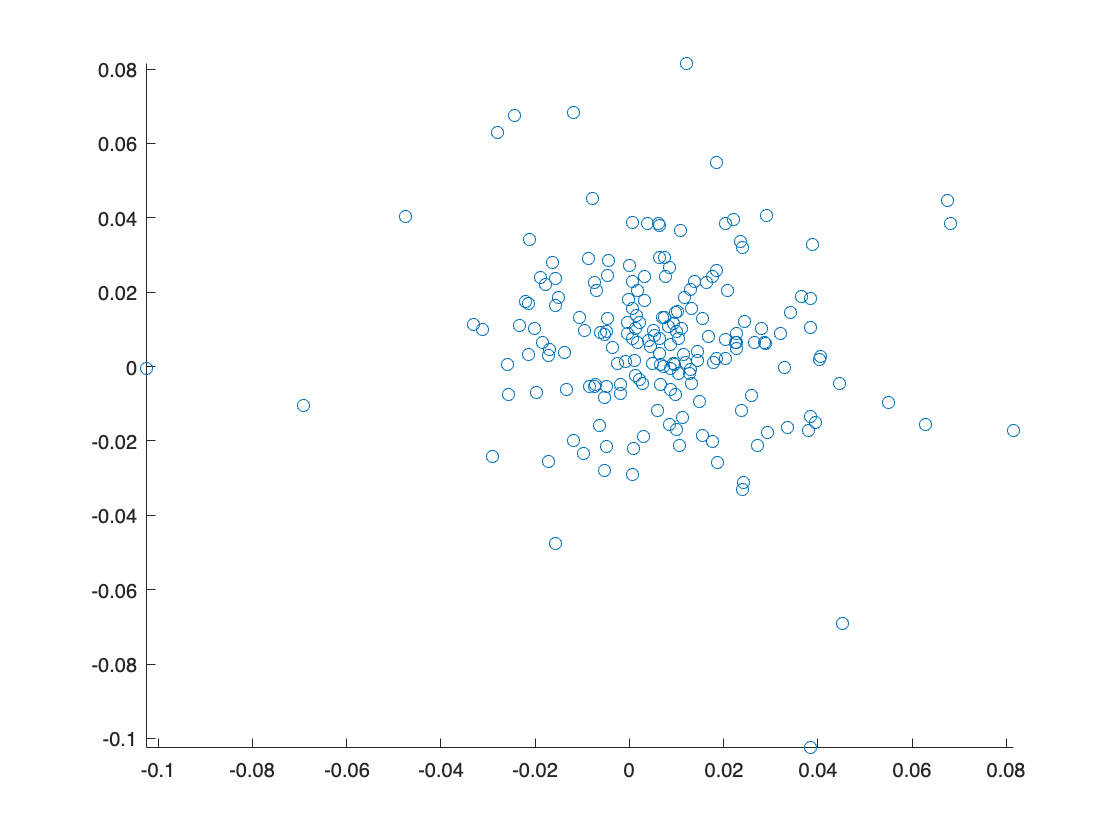

scatter(ASSETCL_log_diff_array(:,1), YLag)

**Using ALSI as a sample TRI series**

SIG_aligned_dataTable2lag = SIG_aligned_dataTable;
% scatter(ASSETCL_dataTable.Time

% Visualise the data on a single plot
%plot the timeseries
plot(SIG_aligned_dataTable2lag.("JALSHTR Index"))
ylabel("Returns")
xlabel("Time")
title("TRI for ALSI")
%include the legend
legend(SIG_aligned_dataTable2lag.Properties.Description,Location="northwest")

- We need **risk drivers** to be **homogenous** over time but don't need to be iid.

- **Invariants** need to be **iid** across time, *however, * weaker assumption of **ergodicity** will suffice (and check stationarity)

*"If the idea is that one wants to predict the trend of the time series into the future using extrapolation of the historical time series, the time series needs to be stationary and ergodic." - From proposal *

Condition a.) of risk drivers 'the risk driver Y_t needs yp completely specify thr securtiy price at any give time along with the securtiy t&cs. However, if we have Stock prices (p) we know that prices are non-homogenous eg. in the fixed income field, prices converge to the face value of zero coupon bonds as maturity approaches.

**Test for 1-2:**

**1. Test for homogeneity**

see: https://www.xlstat.com/en/solutions/features/homogeneity-tests-for-time-series#:~:text=What%20are%20homogeneity%20tests%20for,at%20which%20a%20change%20occurs.

**2. Test for iid, ergodicity and stationarity: **

IID: Scatter plot of compound returns log(S_t+1/ S_t) if is circular the variable will be a candidate for an invariant. 

Ergodicity:  

Test for stationarity using the augmented-dickey-fuller (ADF) test below indicates that we should not reject the H0 and that the series is a unit root process. Therefore the ALSI TRI is **nonstationary**. 

Therefore we need to adapt P to satisfy condition a.). The log price series is homogenous  

Test for stationarity using the augmented-dickey-fuller (ADF) test below indicates that we should not reject the H0 and that the series is a unit root process. Therefore the ALSI TRI is **nonstationary**. 

adftest(SIG_aligned_dataTable2lag.("JALSHTR Index"))

plot(SIG_aligned_dataTable2lag.("JALSHTR Index"));
title('Simulated Time Series')
xlabel('t')
ylabel('ALSITR')
close all

subplot(2,1,1)
autocorr(SIG_aligned_dataTable2lag.("JALSHTR Index"))
subplot(2,1,2)
parcorr(SIG_aligned_dataTable2lag.("JALSHTR Index"))
close all

**A log-normally distributed random variable is one whose logarithm is a normally distributed random variable.)**

% Log all columns of x and return as a new timetable object
% lg_ASSETCL = varfun(@(x) log(x), x, 'OutputFormat', 'timetable');
% 
% % Copy the metadata from x to x_log
% lg_ASSETCL.Properties.Description = x.Properties.Description;
% lg_ASSETCL.Properties.VariableDescriptions = x.Properties.VariableDescriptions;
% lg_ASSETCL.Properties.VariableUnits = x.Properties.VariableUnits;


TO DO: figure out how to get the ln(S_(t+1)/S_(t))

Issue: logging a timetable object OR lagging a double if we extract the ALSI series itself OR find a way to extract the ALSI series as a timetable with time stamps

plot(lg_ALSITR)

Scatter plot of compound returns log(S_t+1/ S_t)

lag_lg_ASLITR = lag(lg_ALSITR ,1);

plot(lg_ALSITR, lag_lg_ASLITR)

n_ALSI = normalize(ALSITR);
plot(n_ALSI)

histogram(n_ALSI)


**Need to calculate returns: will use geometric returns as they are ergodic over time and HS-FP requires the invariants to be IID or the more weaker assumption of ergodicity **

If our risk driver is the assets TRI we can calculate the geometric returns to obtain the invariant series as the geometric returns are ergodic (